# Convolution Filtering

The term filtering generally refers to the process of manipulating the frequency content of a signal. If we reduce the high frequency portion of the signal while letting the low-frequency portion remain, we are filtering the signal. 

This type of filter is called a smoothing filter. Because by reducing high frequencies, we reduced the rapid changes in the signal, which makes the signal change more slowly over time, which corresponds to a smoother looking shape.

Also called a low-pass filter

## Sample

Fs = 44100;
T = 5;
t = [0:1/Fs:T];
[yg, Fsg] = audioread('guitartune.wav');
ygresamp = interp1([0:1/Fsg:(length(yg)-1)/Fsg],yg(:,1),t);
%Salt & pepper noise
sprate = 10;
%White noise 
sigma = 0.03;
rng(0);
spnoise = saltpeppernoise(sprate, t, Fs);
wnoise = sigma*randn(size(t));
ygnoisy = ygresamp+spnoise+wnoise;

## Creating the Box Filter

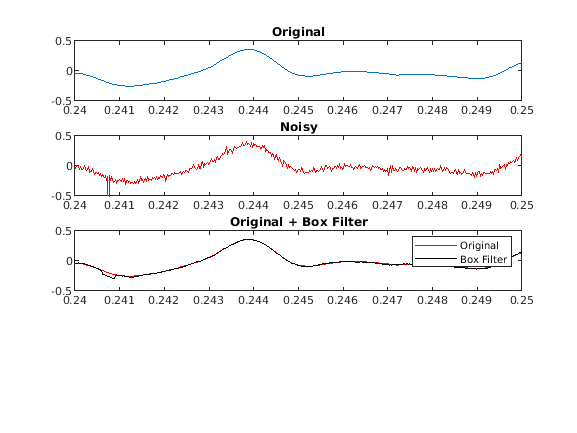

W = 13; %box size
ygbox = conv(ygnoisy, ones(W,1)/W,'same');
%2nd parameter Filter weigths
%which clips the left and right sides of the results so that the output has the same size as ygnoisy. By default, convolution will widen this signal at the front end by W divided by 2 entries. Convolution widens the signal because the windowed average starts with the window only containing the very first entry of the signal, and it's centered to the left of the signal by W over 2 entries, and ends with the window containing only the very last entry of the signal with its center to the right of the last entry by W divided by 2. Thus, the resulting signal after convolution, ends up being wider. But by using the same argument, we tell the convolution function that we want the window to start, centered on the first entry, and end centered on the last entry of the signal. So that the output signal has the same size.
figure(1);
subplot(4,1,1);
plot(t,ygresamp);
title('Original');
axis([0.24 0.25 -0.5 0.5]);
subplot(4,1,2);
plot(t,ygnoisy,'r');
title('Noisy');
axis([0.24 0.25 -0.5 0.5]);
subplot(4,1,3);
plot(t,ygresamp,'r');
title('Original + Box Filter');
axis([0.24 0.25 -0.5 0.5]);
hold on;
plot(t,ygbox,'k');
legend('Original', 'Box Filter');

## Creating Gaussian Filter

A Gaussian filter places more weight on samples near the middle of the filter window and less weight on those towards the edge of the filter window. The Gaussian filter turns out to be mathematically ideal for a number of noise reduction applications. The sharpness or spread of the Gaussian is controlled by a parameter typically termed Sigma, because Sigma is used to represent one standard deviation of the normal Gaussian distribution. 

While a Gaussian function extends in both directions towards infinity and never truly reaches zero, in practice, it tapers off to near zero numbers very quickly,. So we can limit the Gaussian to a small window size. 

It's a common rule of thumb to choose the window size to be six times the Gaussian Sigma, so that three standard deviations of the Gaussian are included in both directions. Here, we already have our width W, so we set Sigma equal to W divided by 6.

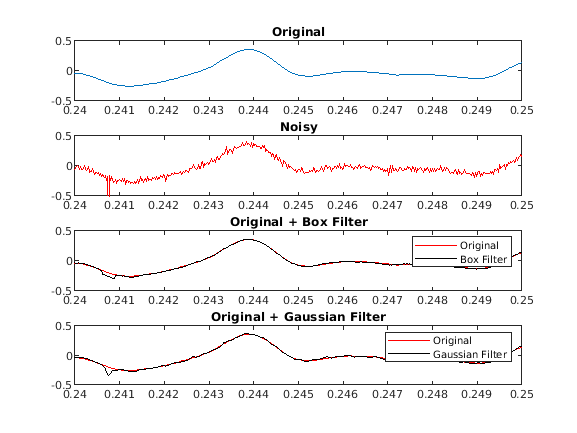

sigma = W/6;
gaussianfilter = fspecial('gaussian', [1,W], sigma);
yggauss = conv(ygnoisy, gaussianfilter, 'same');
subplot(4,1,4);
plot(t,ygresamp,'r');
title('Original + Gaussian Filter');
axis([0.24 0.25 -0.5 0.5]);
hold on;
plot(t,yggauss,'k');
legend('Original', 'Gaussian Filter');

## Finite Impulse Response Filter

produce a response to a finite signal that diminishes to zero over time, as opposed to infinite impulse response filters, which can theoretically go on forever.

Impulse Response is like the Echo 

yfilt = fir1(W,5000/(Fs/2),'high');%high - for high pass filter

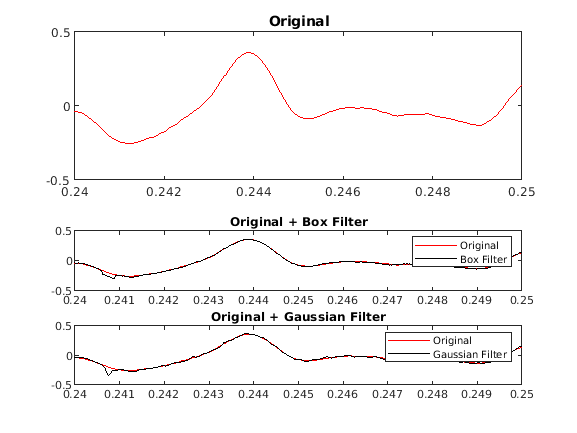

ygfir = conv(ygresamp,yfilt,"same");
figure(2)
subplot(2,1,1);
plot(t,ygresamp,'r');
axis([0.24 0.25 -0.5 0.5]);
title('Original');

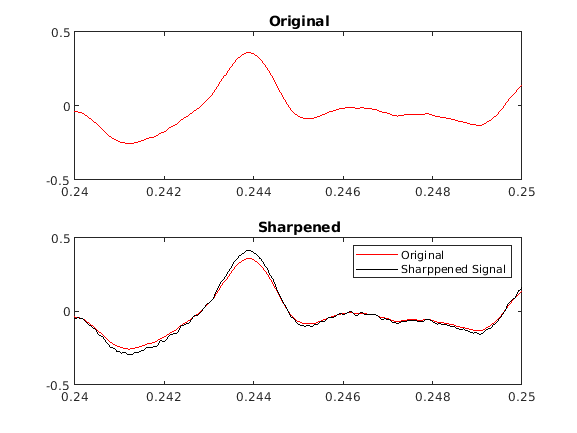

subplot(2,1,2);
plot(t,ygresamp,'r');
title('Sharpened');
axis([0.24 0.25 -0.5 0.5]);
hold on;
ygsharp = ygresamp+10*ygfir;
plot(t,ygsharp,'k');
legend('Original', 'Sharppened Signal');